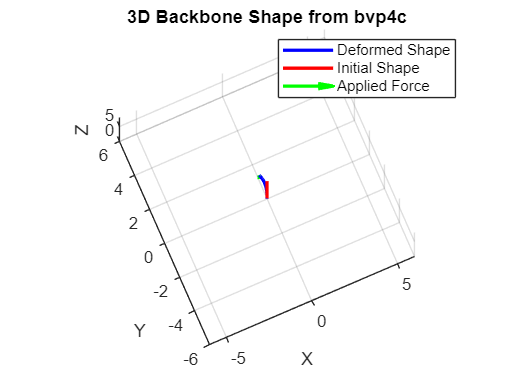

%This is a test file for beam bending simulation

clear, close all


%Ok now trying 3D with same numbers

% Parameters
EI = 0.7;         % Bending stiffness
GJ = .7;
r = 5 / pi;        % Robot radius
n = 1;             % Number of segments
N = 1000;         % Number of discretization points
% Initial actuator positions
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);


% Generate curvature and segment info
[T, act1, act2, act3, curvature, Lck, beta, theta] = ...
    gen_transform_2(6, 6, 6, r, act_11_start, act_12_start, act_13_start, Base_coord);

%Force applied at tip, N
Fx = 0.0; 
Fy = 0.01; 
Fz = -.2;

s_vals = linspace(0, Lck, N);

% Angle functions representing intrinsic curvature (constant curvature)
theta_init = theta * ones(size(s_vals));               % Constant bending direction
%phi_init = (pi/2) - beta * s_vals / Lck;
beta_init = beta * s_vals / Lck;      
% Initialize position array
p_init = zeros(3, N);

% Integrate tangent vector to get position
for i = 2:N
    ds = s_vals(i) - s_vals(i-1);
    th = theta_init(i-1);
    bt = beta_init(i-1);

    tangent = [sin(bt)*cos(th);
               sin(bt)*sin(th);
               cos(bt)];
    p_init(:, i) = p_init(:, i-1) + tangent * ds;
end


%NEED TO FIGURE OUT HOW TO GET THE 3D BENDING TO WORK AND GRAPH IT
%STARTING WITH AN INITIAL CONFIGURATION
%IT MUST KEEP THE SAME RADIUS OF CURVATURE (AND TWIST?) 
% - FEED INTO BOUNDARY CONDITIONS
%SPECIFICALLY SIGMA'(0) = -1/R


% Solve BVP
options = bvpset('RelTol',1e-5,'AbsTol',1e-7);

function dy = eul_fun_cosserat(s, y, EI, p_base, F)
    t = y(1:3);
    p = y(4:6);

    r = p - p_base; % moment arm from base
    M = cross(r, F);

    dt = M / EI;

    dy = zeros(6,1);
    dy(1:3) = dt;
    dy(4:6) = t;
end

function res = bc_fun_cosserat(ya, yb)
    t_base = [0; 0; 1];   % vertical
    p_base = [0; 0; 0];
    res = [...
        ya(1:3) - t_base;   % fixed orientation at base
        ya(4:6) - p_base    % fixed position at base
    ];
end

function yinit = guess_cosserat(s, L)
    t = [0; 0; 1];      % initial tangent
    p = [0; 0; s];      % vertical beam
    yinit = [t; p];
end

%p_tip = [0; 0; Lck];  % initial tip position
p_base = [0; 0; 0];
F = [Fy; -Fx; Fz];    % global force

% Initial mesh
solinit = bvpinit(linspace(0, Lck, 50), @(s) guess_cosserat(s, Lck));

sol = bvp4c(@(s,y) eul_fun_cosserat(s, y, EI, p_base, F), @bc_fun_cosserat, solinit);

s = sol.x;
y = sol.y;

% Solve with bvp4c

p_def = y(4:6,:);

figure
% Plot deformed shape
plot3(p_def(1,:), p_def(2,:), p_def(3,:), 'b-', 'LineWidth', 2);
hold on;

% Plot initial curved shape
plot3(p_init(1,:), p_init(2,:), p_init(3,:), 'r-', 'LineWidth', 2);

title('Initial (Zero-Force) Curved Shape');
% Applied force arrow
quiver3(p_def(1,end), p_def(2,end), p_def(3,end), Fx/sqrt(Fx^2+Fy^2+Fz^2), Fy/sqrt(Fx^2+Fy^2+Fz^2), Fz/sqrt(Fx^2+Fy^2+Fz^2), ...
    'Color', 'green', 'LineWidth', 2, 'AutoScaleFactor', 1, 'MaxHeadSize', 10);

xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
xlim([-6 6])
ylim([-6 6])
zlim([0 8])
title('3D Backbone Shape from bvp4c');
legend('Deformed Shape','Initial Shape',  'Applied Force', 'Location', 'best');




hold off

Functions


function dy = eul_fun(x,y,EI,R,Fx,Fy)
    dy = zeros(1,2);
    dy(1) = y(2);
    dy(2) = 1/EI*(-Fx*cos(y(1))+Fy*sin(y(1)));
 end



function [T_k, act_1_end, act_2_end, act_3_end, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, act_1_start, act_2_start, act_3_start, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    % actuator end point calculation
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
end